# Integrator Lab: Solving First Order ODEs in MATLAB and Picard Approximation

This lab will teach you to numerically solve first order ODEs using a built in MATLAB integrator, `ode45`.  `ode45` is a good, general purpose tool for integrating first order equations (and first order systems). It is not always the right algorithm, but it is usually the right algorithm to try first. This lab will also teach you how to manipulate symbolic functions in MATLAB.

You will learn how to use the `ode45` routine, how to interpolate between points, and how MATLAB handles data structures. You will also learn how to use MATLAB for exact symbolic calculations and write your own Picard approximation code.

Opening the m-file lab2.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are eight exercises in this lab that are to be handed in at the end of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file and submit it online using Quercus.

## Student Information

Student Name: Yoonho Kim

Student Number: 1008035635

## Set up an inline function representation of an ODE and solve it

MATLAB has many built in routines for solving differential equations of the form

`y' = f(t,y)`

We will solve them using `ode45`, a high precision integrator. To do this, we will need to construct an inline function representation of `f`, an initial condition, and specify how far we want MATLAB to integrate the problem. Once we have set these, we pass the information to `ode45` to get the solution.

For a first example, we will solve the initial value problem

`y' = y, y(0) = 1`

which has as its answer `y = e^t`.

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y;

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 2;

soln = ode45(f, [t0, t1], y0);

## Examining the output

When we execute the `ode45`, it returns a data structure, stored in soln. We can see the pieces of the data structure with a display command:

disp(soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2]
          y: [1 1.2214 1.4918 1.8221 2.2255 2.7183 3.3201 4.0552 4.9530 6.0496 7.3891]
      stats: [1×1 struct]
      idata: [1×1 struct]



## Understanding the components of the solution data structure

The most important elements of the data structure are stored in the `x` and `y` components of the structure; these are vectors. Vectors `x` and `y` contain the points at which the numerical approximation to the initial vlaue problem has been computed. In other words, `y(j)` is the approximate value of the solution at `x(j)`.

**NOTE:** Even though we may be studying a problem like `u(t)` or `y(t)`, MATLAB will always use `x` for the independent variable and `y` for the dependent variable in the data structure.

Pieces of the data structure can be accessed using a period, as in C/C++ or Java. See the examples below:

% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(soln.x);

         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000



% Display the the corresponding approximatations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(soln.y);

    1.0000    1.2214    1.4918    1.8221    2.2255    2.7183    3.3201    4.0552    4.9530    6.0496    7.3891




% Display the approximation of the solution at the 3rd point:
fprintf(' Third element of the vector of t values: %g\n',soln.x(3));

 Third element of the vector of t values: 0.4


fprintf(' Third element of the vector of y values: %g\n',soln.y(3));

 Third element of the vector of y values: 1.49182


## Visualizing and comparing the solution

We can now visualize the solution at the computed data points and compare with the exact solution.

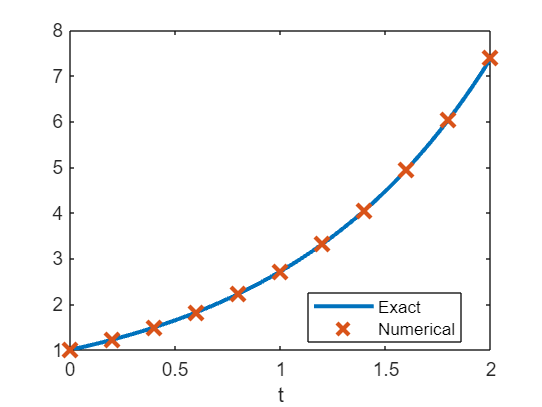

% Construct the exact solution
tt = linspace(0,2,50);
yy = exp(tt);

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
legend('Exact', 'Numerical','Location','Best');

## Exercise 1

Objective: Solve an initial value problem and plot both the numerical approximation and the corresponding exact solution.

Details: Solve the IVP

`y' = y tan t + sin t, y(0) = -1/2`

from `t = 0` to `t = pi`.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Your submission should show the construction of the inline function, the use of ode45 to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

% Solution for Exercise 1
f = @(t,y) y*tan(t) + sin(t);

t0 = 0

t0 = 0

y0 = -1/2

y0 = -0.5000

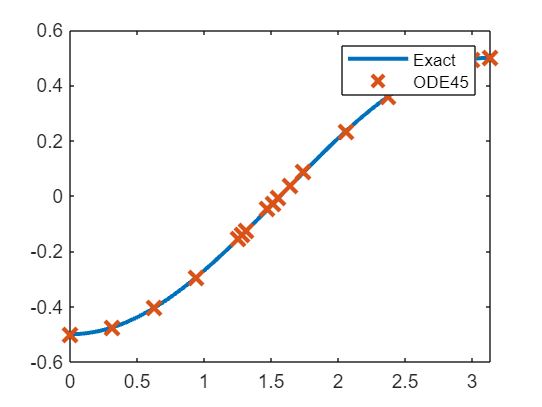


t1 = pi; % Upper bound

solution = ode45(f, [t0, t1], y0); % Compute solution using ode45

% Constructing exact solution
% Exact solution: y = (sint)^2 / 2cost - 1/2cost
tvals = linspace(0,pi,100);
yvals = (((sin(tvals)).^2 )./ (2.*cos(tvals))) - (1./(2.*cos(tvals)));

% Plotting exact solution and ode45 solution on same graph
plot(tvals, yvals, solution.x,solution.y, 'x', 'MarkerSize',10, 'LineWidth', 2)
legend('Exact', 'ODE45')

## Computing an approximation at a specific point

As you should be able to see by examining `soln.x`, ode45 returns the solution at a number of points between `t0` and `t1`. But sometimes we want to know the solution at some intermediate point.

To obtain this value, we need to interpolate it in a consistent way. Fortunately, MATLAB provides a convenient function, `deval`, specifically for this.

% Compute the solution at t = .25:
deval(soln, .25)

ans = 1.2840


% Compute the solution at t = 1.6753:
fprintf(' Solution at 1.6753: %g\n', deval(soln, 1.6753));

 Solution at 1.6753: 5.3404



% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(.45, 1.65, 10);
deval(soln, tinterp)

ans =     1.5683    1.7920    2.0476    2.3396    2.6734    3.0547    3.4903    3.9882    4.5570    5.2070



% Alternatively:
deval(soln, linspace(.45, 1.65, 10))

ans =     1.5683    1.7920    2.0476    2.3396    2.6734    3.0547    3.4903    3.9882    4.5570    5.2070


## Exercise 2

Objective: Interpolate a solution at a number of grid points

Details: For the solution you computed in exercise 1, use deval to compute the interpolated values at 10 grid points between 2 and 3.

% Solution for Exercise 2
interp = linspace (2, 3, 10)

interp =     2.0000    2.1111    2.2222    2.3333    2.4444    2.5556    2.6667    2.7778    2.8889    3.0000



deval(solution, interp);

## Errors, Step Sizes, and Tolerances

As you may have noticed, in contrast to the IODE software, at no point do we set a step size for our solution. Indeed, the step size is set adaptively to conform to a specified error tolerance.

Roughly speaking, given the solution at `(t_j, y_j)`, `ode45` computes two approximations of the solution at `t_{j+1} = t_j + h`; one is of greater accuracy than the other. If the difference is below a specified tolerance, the step is accepted and we continue. Otherwise the step is rejected and the smaller step size, `h`, is used; it is often halved.

We can compute the global truncation error at each solution point, figure out the maximum error, and visualize this error (on a linear-log scale):

% Compute the exact solution
yexact = exp(soln.x);

% Compute the pointwise error; note the use of MATLAB's vectorization
err = abs(yexact - soln.y);

disp(err);

   1.0e-06 *

         0    0.0152    0.0371    0.0679    0.1106    0.1688    0.2475    0.3526    0.4922    0.6764    0.9179




fprintf('maximum error: %g \n', max(err));

maximum error: 9.17923e-07 


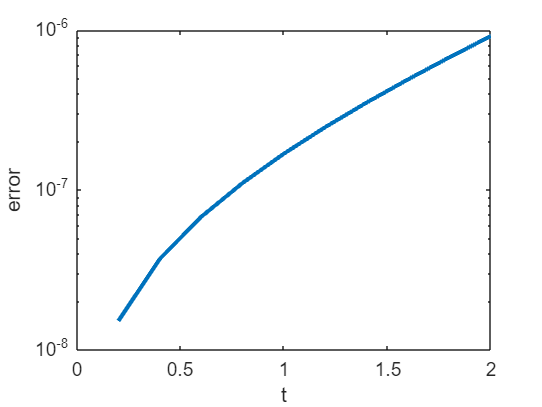


semilogy(soln.x, err, 'LineWidth', 2);
xlabel('t');
ylabel('error');

## Exercise 3

Objective: Examine the error of a solution generated by `ode45`

Details: For your solution to exercise 1, compute the pointwise error, identify the maximum value of the error, and visualize the error on a linear-log plot (use semilogy to plot the log of the error vs. t). Write in the comments where the error is largest, and give a brief (1-2 sentences) explanation of why it is largest there. Make sure to label your axes.

% Solution for Exercise 3
yexac = (((sin(solution.x)).^2) ./ (2.*cos(solution.x))) - (1./(2.*cos(solution.x)));
error = abs(yexac - solution.y);
disp(error); % Display error values

   1.0e-04 *

  Columns 1 through 12

         0    0.0001    0.0006    0.0021    0.0070    0.0077    0.0087    0.0230    0.0408    0.1807    0.0254    0.0114

  Columns 13 through 17

    0.0068    0.0055    0.0047    0.0043    0.0043




fprintf("The max error is: %g \n", max(error));

The max error is: 1.8068e-05 



[maxerror, Index] = max(error) % Find the max error

maxerror = 1.8068e-05

Index = 10

solution.x(10) % Max error occurs at x = 1.5588

ans = 1.5588

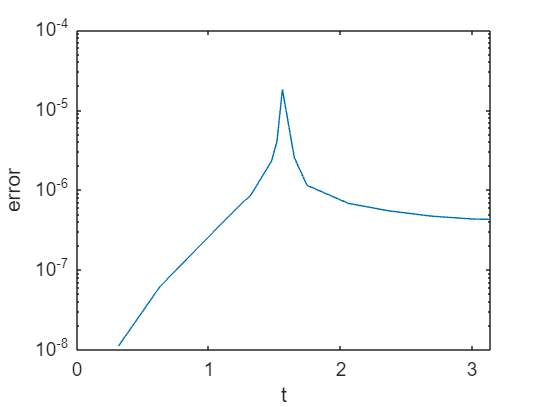


semilogy(solution.x, error); % Plot error graph
xlabel('t');
ylabel('error');


% EXPLANATION FOR MAX ERROR
%{ The max error occurs at x = 1.558 and is 1.806e-5. The maximum error occurs here
% because in the graph of the actual solution, the point where max error
% occurs corresponds directly to the point of inflection in the graph where
% the concavity of the graph changes.

## Exercise 4

Objective: Solve and visualize a nonlinear ode using ode45

Details: Solve the IVP

`y' = 1 / y^2 , y(1) = 1`

from `t=1` to `t=10` using `ode45`. Find the exact solution and compute the maximum pointwise error. Then plot the approximate solution and the exact solution on the same axes.

Your solution should show the definition of the inline function, the computation of its solution in this interval, the computation of the exact solution at the computed grid points, the computation of the maximum error, and a plot of the exact and approximate solutions.

%Your axes should be appropriately labeled and include a legend.
f = @(t,y) 1./(y.^2) % Inline function definition

f = function_handle with value:
    @(t,y)1./(y.^2)


t0 = 1; % Initial conditions and upper bounds
t1 = 10;
y0 = 1;

solution1 = ode45(f,[t0,t1],y0); % Computation of solution using ode45

% Formation of exact solution
tvalues = linspace(1,10,100); % Create an array to contain tvalues
yvalues = (3.*tvalues -2).^(1/3) % Compute solution for each corresponding tvalue

yvalues =     1.0000    1.0837    1.1562    1.2205    1.2787    1.3321    1.3814    1.4275    1.4708    1.5117    1.5505    1.5874    1.6227    1.6565    1.6890    1.7203    1.7505    1.7796    1.8079    1.8353    1.8619    1.8878    1.9129    1.9375    1.9614    1.9847    2.0075    2.0299    2.0517    2.0731    2.0940    2.1145    2.1347    2.1544    2.1738    2.1929    2.2117    2.2301    2.2482    2.2661    2.2836    2.3009    2.3180    2.3348    2.3513    2.3677    2.3838    2.3997    2.4153    2.4308


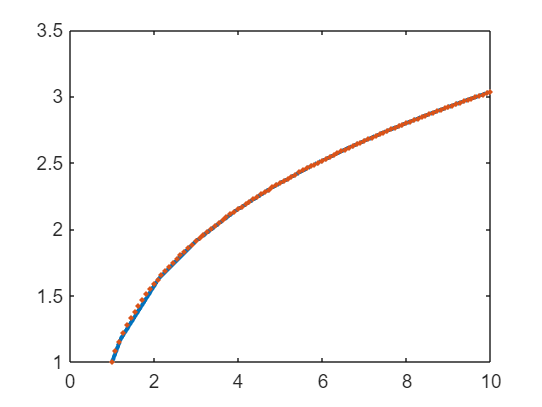


plot(solution1.x,solution1.y, tvalues,yvalues, 'x', 'MarkerSize', 2, 'LineWidth', 2)


% Computing error

yexa = (3.*(solution1.x) -2).^(1/3) % Calculate exact values using formula

yexa =     1.0000    1.1703    1.6265    1.9132    2.1329    2.3148    2.4718    2.6111    2.7370    2.8522    2.9588    3.0366


error = abs(yexa - solution1.y); % Calculate second set of errors

fprintf("The max error is: %g\n", max(error));

The max error is: 0.0017118


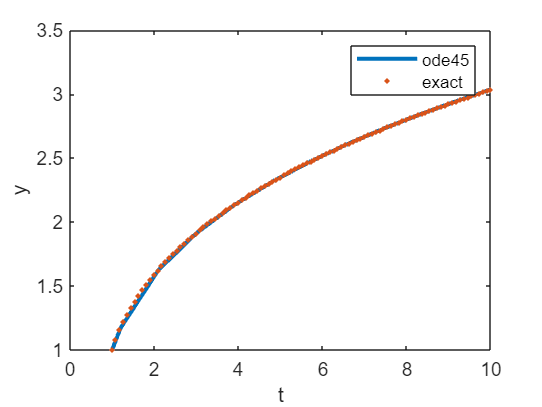


plot(solution1.x,solution1.y, tvalues,yvalues, 'x', 'MarkerSize', 2, 'LineWidth', 2)
xlabel('t');
ylabel('y');
legend("ode45", "exact")

## Exercise 5

Objective: Solve and visualize an ODE that cannot be solved by hand with `ode45`.

Details: Solve the IVP

`y' = 1 - t y / 2, y(0) = -1`

from `t=0` to `t=10`.

Your solution should show you defining the inline function, computing the solution in this interval, and plotting it.

Your axes should be appropriately labeled

% Solution for Exercise 5
func = @(t,y) 1 - t.*(y./2) % Inline function definition

func = function_handle with value:
    @(t,y)1-t.*(y./2)


t0 = 0 % Setup initial conditions and bounds

t0 = 0

t1 = 10

t1 = 10

y0 = -1

y0 = -1

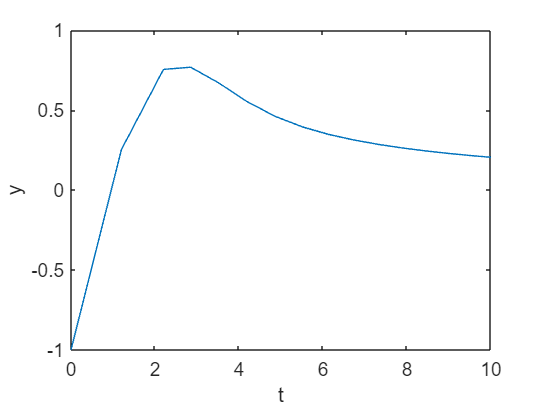


solutn = ode45(func, [t0, t1], y0); % Compute soln with ode45

plot(solutn.x, solutn.y) % Plot of solution
xlabel('t');
ylabel('y');

## Exercise 6 - When things go wrong

Objective: Solve an ode and explain the warning message

Details: Solve the IVP:

`y' = y^3 - t^2, y(0) = 1`

from `t=0` to `t=1`.

Your solution should show you defining the inline function, and computing the solution in this interval.

If you try to plot the solution, you should find that the solution does not make it all the way to t = 1.

In the comments explain why MATLAB generates the warning message that you may see, or fails to integrate all the way to t=1. HINT: Try plotting the direction field for this with IODE.

% Solution for Exercise 6
func1 = @(t,y) y.^3 - t.^2; % Inline function
t0 = 0

t0 = 0

t1 = 1

t1 = 1

y0 = 1

y0 = 1

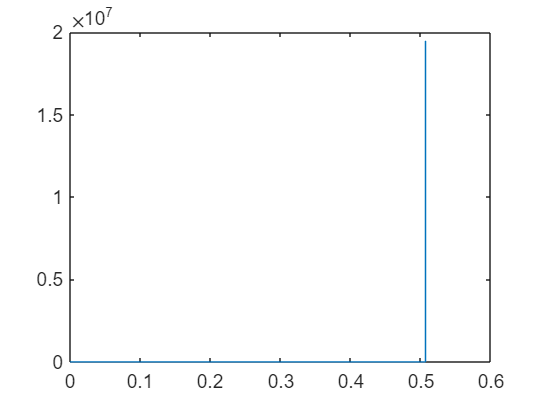


soln2 = ode45(func1, [t0,t1], y0); % Computing soln with ode45

plot(soln2.x, soln2.y); % Plot of solution


% Matlab fails to integrate all the way to t = 1, and only gets as far as a
% bit past t = 0.5. If we plot the directional field for the ODE with the
% specific initial conditions, we can see that the function increases
% towards infinity before t can reach a value of 1. This is why MATLAB
% fails to integrate all the way to t=1. 

## Using symbolic variables to define functions

We can define symbolic variables to let MATLAB know that these variables will be used for exact computations

% Start by defining the variables as symbolic
syms t s x y

% Define a function by simply writing its expression

f = cos(t)

$$f = \cos\left(t\right)$$

g = sin(t)

$$g = \sin\left(t\right)$$

h = exp(2*x)

$$h = {\mathrm{e}}^{2\,x}$$


% We can manipulate these functions

simplify(f^2+g^2)

$$ans = 1$$

diff(h)

$$ans = 2\,{\mathrm{e}}^{2\,x}$$


% We can plot a function defined symbolically using the command |ezplot|.
% Learn about the command |ezplot|:

help ezplot

 ezplot   (NOT RECOMMENDED) Easy to use function plotter
 
  ezplot is not recommended. Use FPLOT or FIMPLICIT instead.
 
    ezplot(FUN) plots the function FUN(X) over the default domain
    -2*PI < X < 2*PI, where FUN(X) is an explicitly defined function of X.
 
    ezplot(FUN2) plots the implicitly defined function FUN2(X,Y) = 0 over
    the default domain -2*PI < X < 2*PI and -2*PI < Y < 2*PI.
 
    ezplot(FUN,[A,B]) plots FUN(X) over A < X < B.
    ezplot(FUN2,[A,B]) plots FUN2(X,Y) = 0 over A < X < B and A < Y < B.
 
    ezplot(FUN2,[XMIN,XMAX,YMIN,YMAX]) plots FUN2(X,Y) = 0 over
    XMIN < X < XMAX and YMIN < Y < YMAX.
 
    ezplot(FUNX,FUNY) plots the parametrically defined planar curve FUNX(T)
    and FUNY(T) over the defau

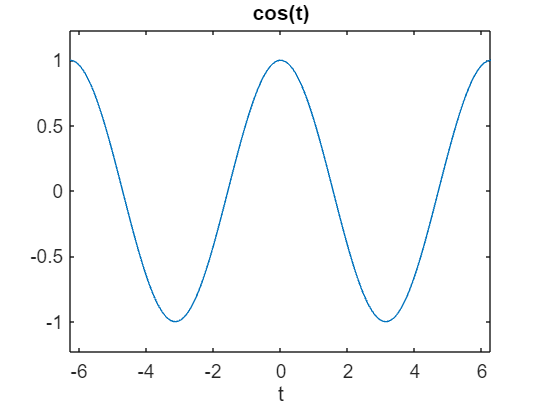


% Plot the function |f(t)| and |h(x)|

ezplot(f)

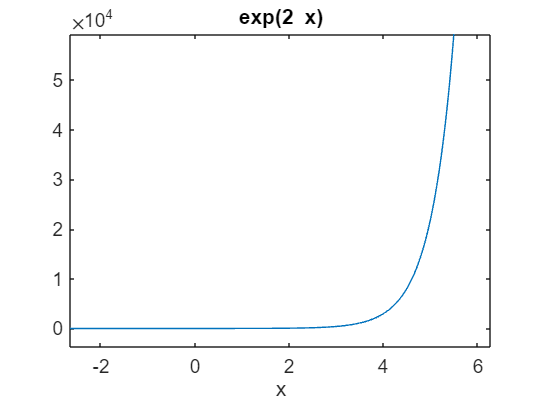

ezplot(h)

If we try to evaluate the function `f(0)`, we get an error message.

The symbolic variables are not meant to be used to evaluate functions, but to manipulate functions, compute derivatives, etc. To evaluate a function using symbolic variables is a little cumbersome:

% We need to substitute the variable by a value:

subs(f,t,pi)

This expression means: In the expression `f`, substitute the variable `t` by the number `pi`.

% If we use a value where the cosine does not have a "nice" expression, we
% need to approximate the result:

subs(f,t,2)

% We need to use the command |eval|

eval(subs(f,t,2))

## Exercise 7

Objective: Define a function using symbolic variables and manipulate it.

Details: Define the function `f(x) = sin(x)cos(x)`

Use MATLAB commands to obtain a simpler form of this function, compute value of this function for `x=pi/4` and `x=1`, and plot its graph.

% Solution for Exercise 7
% GRAPH ISNT PLOTTING
syms t s x y
functi = sin(x)*cos(x)

$$functi = \cos\left(x\right)\,\sin\left(x\right)$$


disp(simplify(functi));

$$\frac{\sin\left(2\,x\right)}{2}$$

disp(diff(functi));

$${\cos\left(x\right)}^{2}-{\sin\left(x\right)}^{2}$$


disp(subs(functi,x,pi/4));

$$\frac{1}{2}$$

disp(subs(functi,x,1));

$$\cos\left(1\right)\,\sin\left(1\right)$$

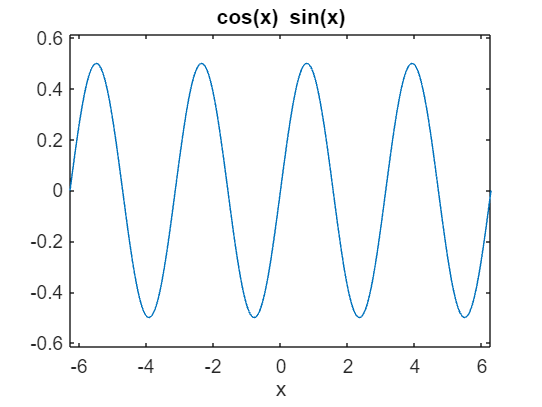

eval(subs(functi,x,pi/4));
eval(subs(functi,x,1));

ezplot(functi);

## Obtaining Picard approximations

Consider an initial value problem

`y' = 1 + y` `y(0) = 0`

First we need to define the variables we will be using

syms t s y;

% We then need to define the function f

f = 1+y; % we define it without the @(t,y) because it is a symbolic function

% We set up our initial approximation phi_0 = 0:

phi=[sym(0)];   % we will keep a list with all the approximations

% Set up a loop to get successive approximations using Picard iterations

N=5;

for i = 1:N
    func=subs(f,y,phi(i));    % prepare function to integrate: y -> previous phi
    func=subs(func,t,s);      % variable of integration is s, so we need to change
    % t -> s
    
    newphi = int(func, s, 0 ,t);   % integrate to find next approximation
    
    phi=cat(2,phi,[newphi]);       % update the list of approximations by adding new phi
end

% Show the last approximation

phi(N+1)

$$ans = \frac{t\,\left(t^{4}+5\,t^{3}+20\,t^{2}+60\,t+120\right)}{120}$$

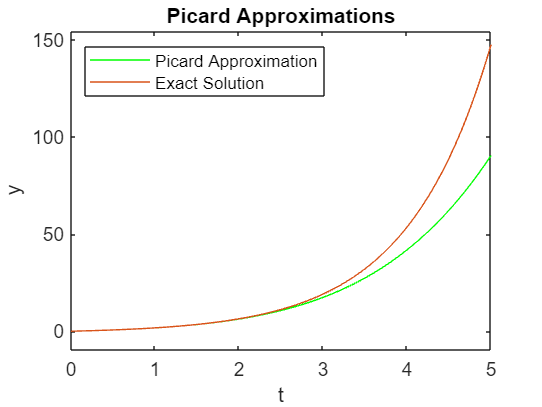


% Plot the approximation just found

picard=ezplot(phi(N+1),[0,5]);
set(picard,'Color','green');         % set the color of the graph to green

% In this case, the exact solution is
%
% |y=e^t-1|
%
% Compare the approximation and the exact solutions

hold on;
exact=ezplot(exp(t)-1,[0,5]);

xlabel('t');
ylabel('y');
title('Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','NorthWest');

## Exercise 8

Find the Picard approximation phi_5. For better efficiency, do not keep all the previous approximations.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Label your axes and include a legend.

HINT. The initial condition has 1 instead of 0, so the Picard method needs to be adapted.

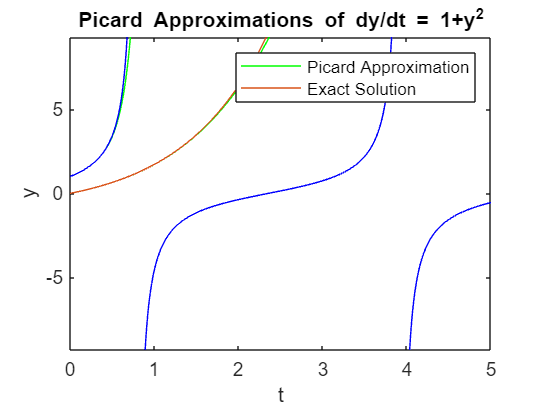

% Solution for Exercise 8
% FIX LEGEND AND EXTRA GRAPHS
syms t s y

f = 1 + y.^2;
phi = [sym(1)];

N = 5;

for j = 1:N
    func = subs(f,y,phi(j));
    func = subs(func, t, s);
    nuphi = 1 + int(func, s, 0 ,t);
    phi = cat(2, phi, [nuphi]);
end

% Show last approximation

phi(N+1);

% Plot the picard approximation

picardapprox = ezplot(phi(N+1), [0,5]);
set(picardapprox, 'Color', 'green');

% The exact solution is |y = tan(t+pi/4)|
% We will compare the exact and picard approximation solutions
% on the same graph

hold on;

exactsoln = ezplot(tan(t+(pi/4)), [0,5]);
set(exactsoln, 'Color', 'blue');

xlabel('t');
ylabel('y');
title('Picard Approximations of dy/dt = 1+y^2');
legend('Picard Approximation', 'Exact Solution', 'Location', 'northeast');